clear
% 导入鸢尾花数据集
load fisheriris

% Train a default classification tree using the entire data set.
% 训练
Mdl = fitctree(meas,species);

% figure;
view(Mdl)  % 文字描述的分类树

Decision tree for classification
1  if x3<2.45 then node 2 elseif x3>=2.45 then node 3 else setosa
2  class = setosa
3  if x4<1.75 then node 4 elseif x4>=1.75 then node 5 else versicolor
4  if x3<4.95 then node 6 elseif x3>=4.95 then node 7 else versicolor
5  class = virginica
6  if x4<1.65 then node 8 elseif x4>=1.65 then node 9 else versicolor
7  class = virginica
8  class = versicolor
9  class = virginica



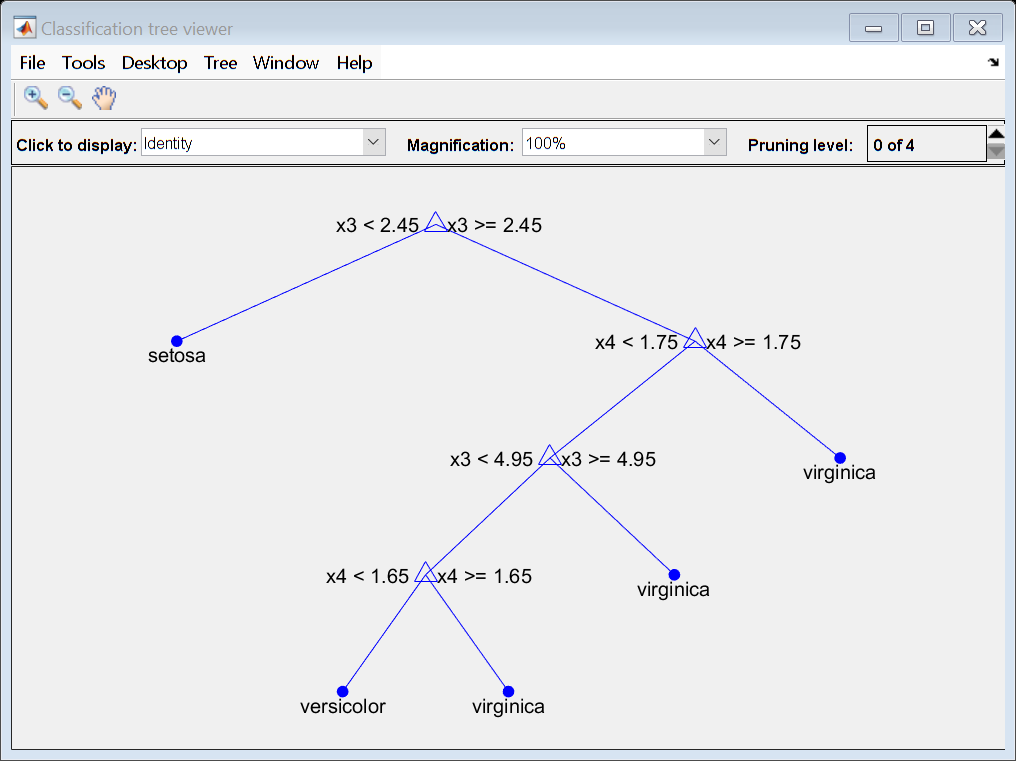

view(Mdl,'Mode','graph')  % 画图描述的分类树

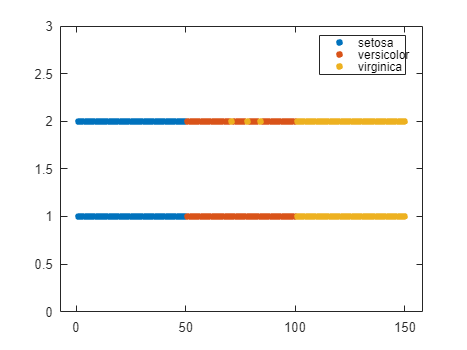


% 预测
cc=predict(Mdl,meas);


% 画图：第1种画法：分类散点图
figure;n=150;
gscatter(1:n,ones(n),species)  % 第一行是原始分类
hold on;
gscatter(1:n,2*ones(n),cc)  % 第2行是预测的分类
ylim([0 3]);

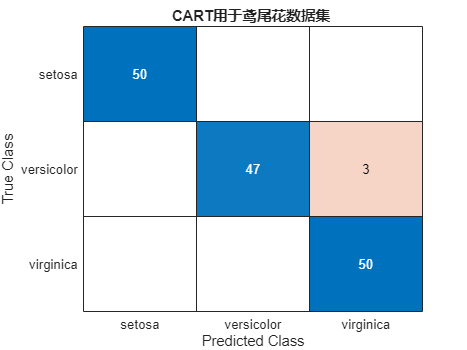


% 画图: 第2种画法：混淆图
figure
cm = confusionchart(species,cc);
cm.Title = 'CART用于鸢尾花数据集 ';


% 评估结果 1： 计算分类模型Mdl中定义的损失函数
resuberror = resubLoss(Mdl)

resuberror = 0.0200


% 评估结果 2： 计算预测不同（错误）的个数，
Ysame = strcmp(cc,species); % True when ==
num_diff=sum(~Ysame) % How many are different?

num_diff = 3

num_diff/n  % 重新计算损失函数

ans = 0.0200